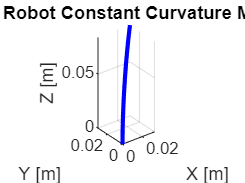

% Parameters
L = 0.1;              % Length of robot [m]
r_c = 0.00375;        % Cable radial distance from center [m]
kappa = 10;           % Curvature [1/m]
phi = pi/4;           % Bending plane angle [rad]

% Discretize arc
s = linspace(0, L, 100);
x = (1/kappa) * (1 - cos(kappa * s)) .* cos(phi);
y = (1/kappa) * (1 - cos(kappa * s)) .* sin(phi);
z = (1/kappa) * sin(kappa * s);

% Plot
figure;
plot3(x, y, z, 'b-', 'LineWidth', 2);
grid on;
xlabel('X [m]');
ylabel('Y [m]');
zlabel('Z [m]');
title('Soft Robot Constant Curvature Model');
axis equal;
view(3);

theta = [0, 2*pi/3, 4*pi/3];  % Cable angular positions
delta_l = -r_c * kappa * L * cos(phi - theta);  % Change in length for each cable

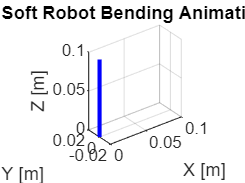

% Parameters
L = 0.1;              % Length of robot [m]
r_c = 0.00375;        % Cable offset [m] (not used in this basic viz)
phi = 0;              % Bending direction: fixed along X-axis
kappa_vals = linspace(0, 20, 100);   % Varying curvature values

% Set up figure
figure;
h = plot3(0,0,0,'b','LineWidth',2);
grid on;
xlabel('X [m]');
ylabel('Y [m]');
zlabel('Z [m]');
axis equal;
xlim([0, 0.1]); ylim([-0.02, 0.02]); zlim([0, 0.1]);
view(3);
title('Soft Robot Bending Animation');

% Animate
for i = 1:length(kappa_vals)
    kappa = kappa_vals(i);
    s = linspace(0, L, 100);
    
    if kappa == 0
        x = zeros(size(s));
        y = zeros(size(s));
        z = s;
    else
        x = (1/kappa) * (1 - cos(kappa * s)) * cos(phi);
        y = (1/kappa) * (1 - cos(kappa * s)) * sin(phi);
        z = (1/kappa) * sin(kappa * s);
    end
    
    set(h, 'XData', x, 'YData', y, 'ZData', z);
    drawnow;
    pause(0.05);
end

for i = length(kappa_vals):-1:1
    kappa = kappa_vals(i);
    s = linspace(0, L, 100);
    
    if kappa == 0
        x = zeros(size(s));
        y = zeros(size(s));
        z = s;
    else
        x = (1/kappa) * (1 - cos(kappa * s)) * cos(phi);
        y = (1/kappa) * (1 - cos(kappa * s)) * sin(phi);
        z = (1/kappa) * sin(kappa * s);
    end
    
    set(h, 'XData', x, 'YData', y, 'ZData', z);
    drawnow;
    pause(0.05);
end